%%INPUTS
run AircraftData.mlx;

Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


%Flight Conditions
h = 25000 %ft

h = 25000

V = 350; %kts
[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
AirDens = DensRat*2.3769*10^-3

AirDens = 0.0011

V=V*1.688

V = 590.8000

AoA = 0;

%Wing Parameters
QuarterSweep = Vanguard.Wing.QuarterChordSweep %deg

QuarterSweep = 0

Df = Vanguard.Fuselage.Diameter;
TaperRatio = Vanguard.Wing.TaperRatio;
S = Vanguard.Wing.S;
b = Vanguard.Wing.b;
AR = Vanguard.Wing.AR;
SweepLE = atand(tand(QuarterSweep)-4/AR*((0-0.25)*(1-TaperRatio)/(1+TaperRatio)))

SweepLE = 2.7695

InstallAngle = 2.59

InstallAngle = 2.5900

LiftCurveSlope = 0.0853 %Per deg

LiftCurveSlope = 0.0853

Yehudi = Vanguard.Wing.Yehudi;
Cr = Vanguard.Wing.Cr

Cr = 16.6139


%Prop Parameters
ThrustAngle = 0

ThrustAngle = 0

Rp = 10

Rp = 10

%HP = 18698*2 %Per engine
PropEff = 0.81

PropEff = 0.8100

zProp = 4

zProp = 4


%Thrust = HP*0.81/V*550
Thrust = 12000*2

Thrust = 24000


x1 = 20.5

x1 = 20.5000

x2 = 42.5

x2 = 42.5000


ThrustCoef = Thrust/(0.5*AirDens*V^2*S) 

ThrustCoef = 0.0822

PropCorrelationParam = S*ThrustCoef/(8*Rp^2) %Use to find f

PropCorrelationParam = 0.1616

Sp = pi*Rp^2

Sp = 314.1593


%DATCOM Figures
PropNormForceCoeff = 0.5 %Pg 1387 Depends on Nominal Blade Anlgle and # of props

PropNormForceCoeff = 0.5000

PropUpwashGradient = 0.4 %Pg 1275 Depends on AR and Prop Distance from 0.25Cr

PropUpwashGradient = 0.4000

f = 1.5 %Pg 1387 Depends on PropCorrelationParam

f = 1.5000

C1 = 0.3 %Pg 1388 Depends on PropCorrelationParam

C1 = 0.3000

C2 = 0.2 %Pg 1388 Depends on PropCorrelationParam

C2 = 0.2000

K = 1 %Pg 1398 Depends on Si/S

K = 1

K1 = 0.8 %Pg 1389 Depends on Prop CorrelationParam, AR, AR immersed

K1 = 0.8000

K2 = 0.8 %Pg 1389 Depends on Prop CorrelationParam, AR, AR immersed

K2 = 0.8000


%For clean wing
daCLmax = 1.2

daCLmax = 1.2000

MaxLiftCoefRatio = 0.9

MaxLiftCoefRatio = 0.9000


%Airfoil Parameters
ZeroLiftAngle = Vanguard.Wing.Airfoil.ZeroLiftAngle;
ClMax = Vanguard.Wing.Airfoil.Clmax;
AirfoilStallAngle = Vanguard.Wing.Airfoil.StallAngle;
Cla = Vanguard.Wing.Airfoil.Cla;


%Clean wing
CLMax = MaxLiftCoefRatio*ClMax

CLMax = 1.4400

WingStallAngle = CLMax/LiftCurveSlope+ZeroLiftAngle+daCLmax

WingStallAngle = 15.0816


%Flapped From Graphs
FlapDeflec = 40 %Deg

FlapDeflec = 40

ddZeroLiftAngle = -0.45 %For Slotted flaps with cf/c = 0.3 at 40deg deflection

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = ddZeroLiftAngle*FlapDeflec

dZeroLiftAngle = -18


%%CALCULATIONS

%Flapped Wing
y1flap=Df/2

y1flap = 7.9165

y2flap=0.75*b/2

y2flap = 44.2500

y3flap=0

y3flap = 0

y4flap=0

y4flap = 0


y3Aileron = 56.05

y3Aileron = 56.0500


cr = 2*S/(b*(1+TaperRatio))

cr = 19.0275


c1flap = YehudiChord(y1flap)

Vanguard = struct with fields:
           MTOW: 147030
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


c1flap = 16.6139

c2flap = YehudiChord(y2flap)

Vanguard = struct with fields:
           MTOW: 147030
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


c2flap = 10.4156

c3flap = YehudiChord(y3flap)

Vanguard = struct with fields:
           MTOW: 147030
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


c3flap = 16.6139

c4flap = YehudiChord(y4flap)

Vanguard = struct with fields:
           MTOW: 147030
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


c4flap = 16.6139


c3Aileron = cr*(1-(1-TaperRatio)*2*y3Aileron/b)

c3Aileron = 8.1818


if y1flap>=Yehudi
    SWF = 2*((c1flap+c2flap)/2*(y2flap-y1flap) + (c3flap+c4flap)/2*(y4flap-y3flap))
else
    SWF = 2*(c1flap*(Yehudi-y1flap)+(c1flap+c2flap)/2*(y2flap-Yehudi) + (c3flap+c4flap)/2*(y4flap-y3flap))
end

SWF = 1.0570e+03



    SweepFactor = (1-0.08*(cosd(QuarterSweep))^2)*(cosd(QuarterSweep))^(3/4)

SweepFactor = 0.9200


dAirfoilStallAngle = -4*10^(-7)*FlapDeflec^4+3*10^(-5)*FlapDeflec^3-0.0019*FlapDeflec^2-0.024*FlapDeflec

dAirfoilStallAngle = -3.1040


AirfoilStallAngleFlapped = AirfoilStallAngle + dAirfoilStallAngle

AirfoilStallAngleFlapped = 12.8960


ZeroLiftAngleFlapped = ZeroLiftAngle + dZeroLiftAngle

ZeroLiftAngleFlapped = -21


ClMaxFlapped = Cla*(AirfoilStallAngleFlapped - ZeroLiftAngleFlapped-daCLmax)

ClMaxFlapped = 3.5855


dClMaxFlapped = ClMaxFlapped - ClMax

dClMaxFlapped = 1.9855

dCLMaxFlapped = dClMaxFlapped*SWF*SweepFactor/S

dCLMaxFlapped = 1.2285


CLMaxFlapped = CLMax + dCLMaxFlapped

CLMaxFlapped = 2.6685


%Powered CLmax



%KN =
KN = 80.7 %ASSUMED

KN = 80.7000


TruePropNormalForceCoeff = PropNormForceCoeff*(1+0.8*(KN/80.7-1))

TruePropNormalForceCoeff = 0.5000


PropPlaneAngle = ThrustAngle + PropUpwashGradient*(AoA+InstallAngle-ZeroLiftAngle)  

PropPlaneAngle = 2.2360


dCLPropNorm = f*TruePropNormalForceCoeff*PropPlaneAngle/57.3*Sp/S*cosd(ThrustAngle)

dCLPropNorm = 0.0059


UpwashGradient = C1 + C2*TruePropNormalForceCoeff

UpwashGradient = 0.4000


PropDownwashAngle = UpwashGradient*PropPlaneAngle

PropDownwashAngle = 0.8944


dWingAoA = -PropDownwashAngle/(1+PropUpwashGradient)

dWingAoA = -0.6389


PropUpwashAngle = PropUpwashGradient*(AoA+InstallAngle-ZeroLiftAngle)

PropUpwashAngle = 2.2360


for x=1:1:27
   
    CL = (x-1)/10
    
    %Inboard Props
    y1 = 19 %ft to centerline of prop
    z1 = x1*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing
    b1 = 2*sqrt(Rp^2-z1^2)
    c1 = cr*(1-(1-TaperRatio)*2*y1/b)
    S1 = b1*c1
    AReff1 = b1/c1
    dSlipstreamDynPressure1 = S*ThrustCoef/(pi*Rp^2)
    dCLWash1 = (1+dSlipstreamDynPressure1)*S1/S*LiftCurveSlope*dWingAoA*K1
    dCLq1 = K1*dSlipstreamDynPressure1*S1/S*CL
    
    %Outboard Props
    y2 = 45.5 %ft to centerline of prop
    z2 = x2*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing
    b2 = 2*sqrt(Rp^2-z2^2)
    c2 = cr*(1-(1-TaperRatio)*2*y2/b)
    S2 = b2*c2
    AReff2 = b2/c2
    dSlipstreamDynPressure2 = S*ThrustCoef/(pi*Rp^2)
    dCLWash2 = (1+dSlipstreamDynPressure2)*S2/S*LiftCurveSlope*dWingAoA*K1
    dCLq2 = K2*dSlipstreamDynPressure2*S2/S*CL
    
    ImmersedRatio = (2*S1+2*S2)/S
    
    CLPowered(x) = CL + K*(4*dCLPropNorm + 2*dCLWash1 + 2*dCLq1 + 2*dCLWash2 + 2*dCLq2)

    alpha(x) = (CL/LiftCurveSlope)+ZeroLiftAngleFlapped
    
end

CL = 0

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1048    0.2238    0.3428    0.4617    0.5807    0.6997    0.8187    0.9377    1.0567    1.1757    1.2947    1.4136    1.5326    1.6516    1.7706    1.8896    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.9339  -18.8678  -17.8017  -16.7356  -15.6695  -14.6034  -13.5373  -12.4712  -11.4051  -10.3390   -9.2729   -8.2068   -7.1407   -6.0746   -5.0085   -3.9424   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 0.1000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0057

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0037

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2238    0.3428    0.4617    0.5807    0.6997    0.8187    0.9377    1.0567    1.1757    1.2947    1.4136    1.5326    1.6516    1.7706    1.8896    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.8678  -17.8017  -16.7356  -15.6695  -14.6034  -13.5373  -12.4712  -11.4051  -10.3390   -9.2729   -8.2068   -7.1407   -6.0746   -5.0085   -3.9424   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 0.2000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0115

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0074

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3428    0.4617    0.5807    0.6997    0.8187    0.9377    1.0567    1.1757    1.2947    1.4136    1.5326    1.6516    1.7706    1.8896    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.8017  -16.7356  -15.6695  -14.6034  -13.5373  -12.4712  -11.4051  -10.3390   -9.2729   -8.2068   -7.1407   -6.0746   -5.0085   -3.9424   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 0.3000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0172

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0111

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4617    0.5807    0.6997    0.8187    0.9377    1.0567    1.1757    1.2947    1.4136    1.5326    1.6516    1.7706    1.8896    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.7356  -15.6695  -14.6034  -13.5373  -12.4712  -11.4051  -10.3390   -9.2729   -8.2068   -7.1407   -6.0746   -5.0085   -3.9424   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 0.4000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0230

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0148

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5807    0.6997    0.8187    0.9377    1.0567    1.1757    1.2947    1.4136    1.5326    1.6516    1.7706    1.8896    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.6695  -14.6034  -13.5373  -12.4712  -11.4051  -10.3390   -9.2729   -8.2068   -7.1407   -6.0746   -5.0085   -3.9424   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 0.5000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0287

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0185

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.6997    0.8187    0.9377    1.0567    1.1757    1.2947    1.4136    1.5326    1.6516    1.7706    1.8896    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -14.6034  -13.5373  -12.4712  -11.4051  -10.3390   -9.2729   -8.2068   -7.1407   -6.0746   -5.0085   -3.9424   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 0.6000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0345

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0223

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8187    0.9377    1.0567    1.1757    1.2947    1.4136    1.5326    1.6516    1.7706    1.8896    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -13.5373  -12.4712  -11.4051  -10.3390   -9.2729   -8.2068   -7.1407   -6.0746   -5.0085   -3.9424   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 0.7000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0402

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0260

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9377    1.0567    1.1757    1.2947    1.4136    1.5326    1.6516    1.7706    1.8896    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -12.4712  -11.4051  -10.3390   -9.2729   -8.2068   -7.1407   -6.0746   -5.0085   -3.9424   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 0.8000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0460

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0297

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0567    1.1757    1.2947    1.4136    1.5326    1.6516    1.7706    1.8896    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -11.4051  -10.3390   -9.2729   -8.2068   -7.1407   -6.0746   -5.0085   -3.9424   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 0.9000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0517

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0334

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1757    1.2947    1.4136    1.5326    1.6516    1.7706    1.8896    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490  -10.3390   -9.2729   -8.2068   -7.1407   -6.0746   -5.0085   -3.9424   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 1

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0575

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0371

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2947    1.4136    1.5326    1.6516    1.7706    1.8896    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -9.2729   -8.2068   -7.1407   -6.0746   -5.0085   -3.9424   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 1.1000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0632

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0408

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2961    1.4136    1.5326    1.6516    1.7706    1.8896    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -8.1043   -8.2068   -7.1407   -6.0746   -5.0085   -3.9424   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 1.2000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0690

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0445

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2961    1.4150    1.5326    1.6516    1.7706    1.8896    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -8.1043   -6.9320   -7.1407   -6.0746   -5.0085   -3.9424   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 1.3000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0747

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0482

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2961    1.4150    1.5339    1.6516    1.7706    1.8896    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -8.1043   -6.9320   -5.7597   -6.0746   -5.0085   -3.9424   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 1.4000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0805

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0519

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2961    1.4150    1.5339    1.6528    1.7706    1.8896    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -8.1043   -6.9320   -5.7597   -4.5873   -5.0085   -3.9424   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 1.5000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0862

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0556

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2961    1.4150    1.5339    1.6528    1.7718    1.8896    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -8.1043   -6.9320   -5.7597   -4.5873   -3.4150   -3.9424   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 1.6000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0920

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0593

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2961    1.4150    1.5339    1.6528    1.7718    1.8907    2.0086    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -8.1043   -6.9320   -5.7597   -4.5873   -3.4150   -2.2427   -2.8763   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 1.7000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.0977

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0631

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2961    1.4150    1.5339    1.6528    1.7718    1.8907    2.0096    2.1276    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -8.1043   -6.9320   -5.7597   -4.5873   -3.4150   -2.2427   -1.0703   -1.8102   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 1.8000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.1035

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0668

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2961    1.4150    1.5339    1.6528    1.7718    1.8907    2.0096    2.1285    2.2466    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -8.1043   -6.9320   -5.7597   -4.5873   -3.4150   -2.2427   -1.0703    0.1020   -0.7441    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 1.9000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.1092

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0705

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2961    1.4150    1.5339    1.6528    1.7718    1.8907    2.0096    2.1285    2.2474    2.3655    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -8.1043   -6.9320   -5.7597   -4.5873   -3.4150   -2.2427   -1.0703    0.1020    1.2743    0.3220    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 2

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.1150

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0742

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2961    1.4150    1.5339    1.6528    1.7718    1.8907    2.0096    2.1285    2.2474    2.3663    2.4845    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -8.1043   -6.9320   -5.7597   -4.5873   -3.4150   -2.2427   -1.0703    0.1020    1.2743    2.4467    1.3881    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 2.1000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.1207

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0779

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2961    1.4150    1.5339    1.6528    1.7718    1.8907    2.0096    2.1285    2.2474    2.3663    2.4853    2.6035    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -8.1043   -6.9320   -5.7597   -4.5873   -3.4150   -2.2427   -1.0703    0.1020    1.2743    2.4467    3.6190    2.4542    3.5203    4.5864    5.6525    6.7186


CL = 2.2000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.1265

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0816

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2961    1.4150    1.5339    1.6528    1.7718    1.8907    2.0096    2.1285    2.2474    2.3663    2.4853    2.6042    2.7225    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -8.1043   -6.9320   -5.7597   -4.5873   -3.4150   -2.2427   -1.0703    0.1020    1.2743    2.4467    3.6190    4.7913    3.5203    4.5864    5.6525    6.7186


CL = 2.3000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.1322

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0853

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2961    1.4150    1.5339    1.6528    1.7718    1.8907    2.0096    2.1285    2.2474    2.3663    2.4853    2.6042    2.7231    2.8415    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -8.1043   -6.9320   -5.7597   -4.5873   -3.4150   -2.2427   -1.0703    0.1020    1.2743    2.4467    3.6190    4.7913    5.9637    4.5864    5.6525    6.7186


CL = 2.4000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.1380

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0890

ImmersedRatio = 0.5747

CLPowered =    -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2961    1.4150    1.5339    1.6528    1.7718    1.8907    2.0096    2.1285    2.2474    2.3663    2.4853    2.6042    2.7231    2.8420    2.9605    3.0795


alpha =   -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -8.1043   -6.9320   -5.7597   -4.5873   -3.4150   -2.2427   -1.0703    0.1020    1.2743    2.4467    3.6190    4.7913    5.9637    7.1360    5.6525    6.7186


CL = 2.5000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.1437

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0927

ImmersedRatio = 0.5747

CLPowered = 1×27
   -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2961    1.4150    1.5339    1.6528    1.7718    1.8907    2.0096    2.1285    2.2474    2.3663    2.4853    2.6042    2.7231    2.8420    2.9609    3.0795


alpha = 1×27
  -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -8.1043   -6.9320   -5.7597   -4.5873   -3.4150   -2.2427   -1.0703    0.1020    1.2743    2.4467    3.6190    4.7913    5.9637    7.1360    8.3083    6.7186


CL = 2.6000

y1 = 19

z1 = 4.4801

b1 = 17.8806

c1 = 15.3510

S1 = 274.4849

AReff1 = 1.1648

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = -0.0107

dCLq1 = 0.1495

y2 = 45.5000

z2 = 4.9953

b2 = 17.3259

c2 = 10.2233

S2 = 177.1271

AReff2 = 1.6948

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = -0.0069

dCLq2 = 0.0964

ImmersedRatio = 0.5747

CLPowered = 1×27
   -0.0120    0.1070    0.2259    0.3448    0.4637    0.5826    0.7015    0.8204    0.9394    1.0583    1.1772    1.2961    1.4150    1.5339    1.6528    1.7718    1.8907    2.0096    2.1285    2.2474    2.3663    2.4853    2.6042    2.7231    2.8420    2.9609    3.0798


alpha = 1×27
  -21.0000  -19.8277  -18.6553  -17.4830  -16.3107  -15.1383  -13.9660  -12.7937  -11.6213  -10.4490   -9.2767   -8.1043   -6.9320   -5.7597   -4.5873   -3.4150   -2.2427   -1.0703    0.1020    1.2743    2.4467    3.6190    4.7913    5.9637    7.1360    8.3083    9.4807


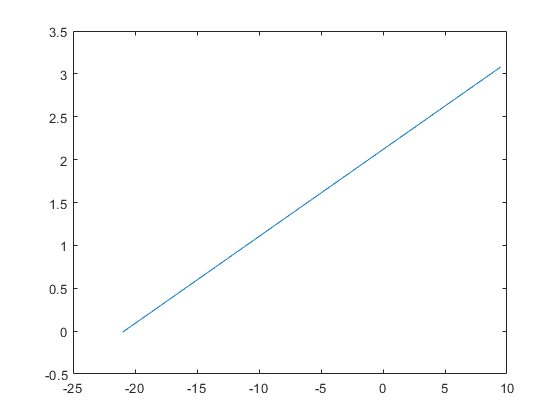


plot(alpha,CLPowered)


%Inboard Props
y1 = 19 %ft to centerline of prop

y1 = 19

z1 = x1*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing

z1 = 4.4801

b1 = 2*sqrt(Rp^2-z1^2)

b1 = 17.8806

c1 = cr*(1-(1-TaperRatio)*2*y1/b)

c1 = 15.3510

S1 = b1*c1

S1 = 274.4849

AReff1 = b1/c1

AReff1 = 1.1648

dSlipstreamDynPressure1 = S*ThrustCoef/(pi*Rp^2)

dSlipstreamDynPressure1 = 0.4114

dCLWash1 = (1+dSlipstreamDynPressure1)*S1/S*LiftCurveSlope*dWingAoA*K1

dCLWash1 = -0.0107

dCLq1 = K1*dSlipstreamDynPressure1*S1/S*CLMaxFlapped

dCLq1 = 0.1534


%Outboard Props
y2 = 45.5 %ft to centerline of prop

y2 = 45.5000

z2 = x2*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing

z2 = 4.9953

b2 = 2*sqrt(Rp^2-z2^2)

b2 = 17.3259

c2 = cr*(1-(1-TaperRatio)*2*y2/b)

c2 = 10.2233

S2 = b2*c2

S2 = 177.1271

AReff2 = b2/c2

AReff2 = 1.6948

dSlipstreamDynPressure2 = S*ThrustCoef/(pi*Rp^2)

dSlipstreamDynPressure2 = 0.4114

dCLWash2 = (1+dSlipstreamDynPressure2)*S2/S*LiftCurveSlope*dWingAoA*K1

dCLWash2 = -0.0069

dCLq2 = K2*dSlipstreamDynPressure2*S2/S*CLMaxFlapped

dCLq2 = 0.0990


ImmersedRatio = (2*S1+2*S2)/S

ImmersedRatio = 0.5747


CLMaxPowered = CLMaxFlapped + K*(4*dCLPropNorm + 2*dCLWash1 + 2*dCLq1 + 2*dCLWash2 + 2*dCLq2)

CLMaxPowered = 3.1612